% CRF PER DUR for RUNNING VS STATIONARY, all vis areas


% complete runSpeed2 analysis first

% then LOAD ind&groupvars4analysis

% % legend info
% 
% reigons = {'V1','LM','AL','AM','control'};
% 
% cons4Axes = {'0','3','6','12','25','50','100'};
% cons4Legend = {'0','0.03','0.063','0.125','0.25','0.5','1'};
% 
% % durs4Axes = {'16','33','66','133','266'};
% durs4Axes = {'66','83','100','133'};
% % durs4Legend = {'16 ms','33 ms','66 ms','133 ms','266 ms'};
% durs4Legend = {'66 ms','83 ms','100 ms','133 ms'};


% VARS 4 FIGS - need indicies for trials that meet criteria
% CONTRAST calc's
% this part needed for any loops involving looping over CONTRAST:

% extract contrast field from stimDetails
for i=1:length(stimDetails); % 1x96 struct, each row is a stim condition , w/colums fields like sf, correctResp, contrasts, etc
    con(i) = stimDetails(i).targContrast; % making vector with list of targ contrast for each condition - some of these will be repeating, since there are only 3 contrasts but 96 stimulus conditions (phase, etc)
end

conOrderedByTrial = con(trialCond); % trial cond is all conditions ordered by trial..its indicies for rows in stimDetail
conOrderedByTrialMeetCriteria = conOrderedByTrial(:,idxOnsetsMeetsCriteria);
uniqueContrasts = unique(con); % for looping over contrast values later


%%  DURATION Calc's
% this part needed for any loops involving looping over DURATION:

% extract contrast field from stimDetails
for i=1:length(stimDetails); % 1 by # stim conditions struct, each row is a stim condition , w/colums fields like sf, correctResp, contrasts, duration, etc
    dur(i) = stimDetails(i).duration; % making vector with list of stim duration for each condition - some of these will be repeating, since there are only 5? durations but many stimulus conditions (phase, etc)
end

durOrderedByTrial = dur(trialCond); 
durOrderedByTrialMeetCriteria = durOrderedByTrial(:,idxOnsetsMeetsCriteria);
uniqueDurations = unique(dur);

%% CON & DUR TOGETHER

% putting together dur & con so that I can index into the trials in order w/trialCond
conAndDur = [con; dur];
% put it in order of trial presentation:
conAndDurOrderedByTrial = conAndDur(:,trialCond); % gives 2 x #trials
conAndDurOrderedByTrialMeetCriteria = conAndDurOrderedByTrial(:,idxOnsetsMeetsCriteria); 


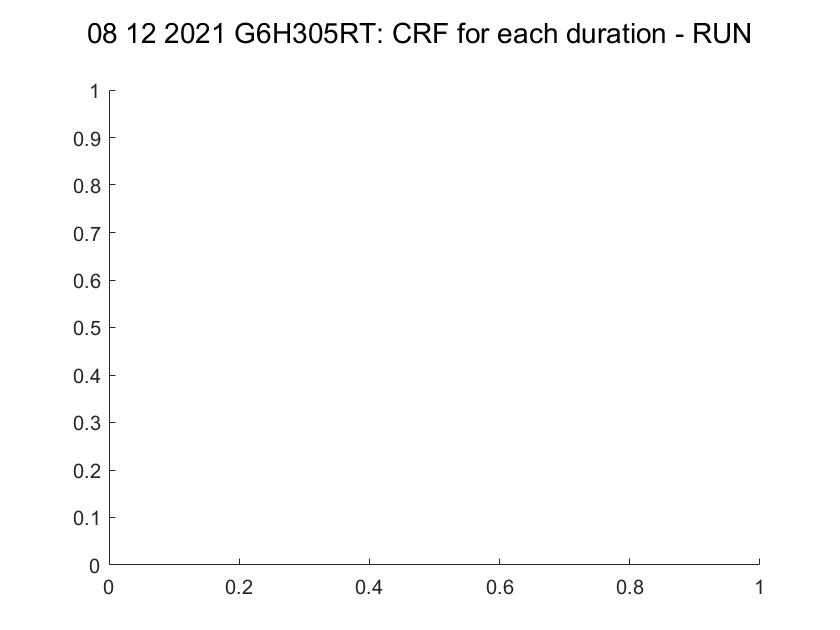

figure 
clear titleText
titleText = sprintf(': CRF for each duration - RUN'); % making char variables for sprintf/title later
suptitle(sprintf('%s', date, subjName, titleText));


clear i
for i = 1:length(xPickedPts) % for each point
    
    clear meanBaselineFramesIthPtCthDthTrials
    clear dthCRF
    clear stdErr
    clear contStdErr

    clear d
    for d = 1:length(uniqueDurations) % at each duration
    
        clear cthDthMeanOverTrialsMeanOverFramesSq5FramesOverTrialsPTSdfof
        clear c
        for c = 1:length(uniqueContrasts) % for each duration at each contrast
            
             % for each POINT, for each DUR, get CRF at the dth dur

             clear cthDthTrials
             cthDthTrials = conAndDurOrderedByTrialMeetCriteria(1,:) == uniqueContrasts(c) & conAndDurOrderedByTrialMeetCriteria(2,:) == uniqueDurations(d);
             numTrials = sum(cthDthTrials);
             
             clear idxCthDthTrial
             idxCthDthTrial = find(cthDthTrials == 1);
             
             clear idxCthDthRUNtrials
             idxCthDthRUNtrials = intersect(idxCthDthTrial,idxRunTrials); % idxRunTrials was made in runSpeed2 script
             
             % clear idxCthDthSTATtrials
             % idxCthDthSTATtrials = idxStatTrials(intersect(idxCthDthTrial,idxStatTrials);
             
             % this is the same as the CRF process from earlier code
             % getting AVG DF/F over 3 FRAMES & dthCthTRIALS for each CONTRAST at this DURATION
             % returns # frames by # trials
             clear sq5FramesOverTrialsPTSdfof
             sq5FramesOverTrialsPTSdfof = squeeze(PTSdfof(i,peakFrameIdx,idxCthDthRUNtrials));
            
             % take the mean over frames
             % returns 1 x # trials
             clear meanOverFramesSq5FramesOverTrialsPTSdfof
             meanOverFramesSq5FramesOverTrialsPTSdfof = mean(sq5FramesOverTrialsPTSdfof,1);
         
             % now take the mean over trials
             clear meanOverTrialsMeanOverFramesSq5FramesOverTrialsPTSdfof 
             meanOverTrialsMeanOverFramesSq5FramesOverTrialsPTSdfof = mean(meanOverFramesSq5FramesOverTrialsPTSdfof);
        
             % now I want to collect each c-th DRF value for this point
             % creates 1 x # contrasts for the d-th duration
             dthCRF(1,c) = meanOverTrialsMeanOverFramesSq5FramesOverTrialsPTSdfof; 
        
             % GET mean BASEline
             % the baseline for each CRF value is the mean of the baseline frames for
             % the ith point and cth contrast
             % get all frames & cth trials
             clear baselineFramesIthPtCthDthTrials
             baselineFramesIthPtCthDthTrials = squeeze((PTSdfof(i,baselineIdx,idxCthDthRUNtrials)));
             % now have baseline frames x trials
             % take mean across trials 
             clear meanBaselineFramesIthPtCthDthTrials
             meanBaselineFramesIthPtCthDthTrials = mean(baselineFramesIthPtCthDthTrials,2);
             % take mean across frames
             meanBaselineFramesIthPtCthDthTrials = mean(meanBaselineFramesIthPtCthDthTrials,1);
            
             % do BASEline CORRECTION
             % subtract the cth baseline from the flourescence at each c
             dthCRF(c) = dthCRF(c)-meanBaselineFramesIthPtCthDthTrials; % clear this var in between subplots

            % STDERR
            % now I want to calulate the StdErr for each CRF point calulated above
            % (one err value for each contrast)
            % that means I want the error over trials, not over frames
            % that info is in the 'meanOverFramesSq5FramesOverTrialsPTSdfof' variable (1 x # trials)
            clear stdErr
            stdErr = std(meanOverFramesSq5FramesOverTrialsPTSdfof)/sqrt(length(idxCthDthRUNtrials)); % length
            contStdErr(1,c) = stdErr; % clear outside j loop
             
        end % end c loop
     
        % once I've got that^ for the d-th duration, plot dth trace on ith subplot:
        subplot(2,3,i) 
        
        % 7 contrasts for x axis
        x_axis = [1:length(uniqueContrasts)];
        errorbar(x_axis,dthCRF,contStdErr,'-s','MarkerSize',3) 
        title(reigons{i})
        
        ylim([-0.025 0.1]) 
        xlim([0, 8])
        ylabel('df/f')
        xlabel('contrast (%)')

        clear xt
        xt={'0'; '3' ; '6' ; '12' ; '25' ; '50'; '100'} ; 
        set(gca,'xtick',1:7); 
        set(gca,'xticklabel',xt);
        
        hold on 
        
    end % end d loop

hold on
legend(durs4Axes)
    
end % end i loop

Undefined function or variable 'idxRunTrials'.


figure 
clear titleText
titleText = sprintf(': CRF for each duration - STAT'); % making char variables for sprintf/title later
suptitle(sprintf('%s', date, subjName, titleText));

clear i
for i = 1:length(xPickedPts) % for each point
    
    clear meanBaselineFramesIthPtCthDthTrials
    clear dthCRF
    clear stdErr
    clear contStdErr

    clear d
    for d = 1:length(uniqueDurations) % at each duration
    
        clear cthDthMeanOverTrialsMeanOverFramesSq5FramesOverTrialsPTSdfof
        clear c
        for c = 1:length(uniqueContrasts) % for each duration at each contrast
            
             % for each POINT, for each DUR, get CRF at the dth dur

             clear cthDthTrials
             cthDthTrials = conAndDurOrderedByTrialMeetCriteria(1,:) == uniqueContrasts(c) & conAndDurOrderedByTrialMeetCriteria(2,:) == uniqueDurations(d);
             numTrials = sum(cthDthTrials);
             
             clear idxCthDthTrial
             idxCthDthTrial = find(cthDthTrials == 1);
             
             % clear idxCthDthRUNtrials
             % idxCthDthRUNtrials = intersect(idxCthDthTrial,idxRunTrials); % idxRunTrials was made in runSpeed2 script
             
             clear idxCthDthSTATtrials
             idxCthDthSTATtrials = intersect(idxCthDthTrial,idxStatTrials);
             
             % this is the same as the CRF process from earlier code
             % getting AVG DF/F over 3 FRAMES & dthCthTRIALS for each CONTRAST at this DURATION
             % returns # frames by # trials
             clear sq5FramesOverTrialsPTSdfof
             sq5FramesOverTrialsPTSdfof = squeeze(PTSdfof(i,peakFrameIdx,idxCthDthSTATtrials));
            
             % take the mean over frames
             % returns 1 x # trials
             clear meanOverFramesSq5FramesOverTrialsPTSdfof
             meanOverFramesSq5FramesOverTrialsPTSdfof = mean(sq5FramesOverTrialsPTSdfof,1);
         
             % now take the mean over trials
             clear meanOverTrialsMeanOverFramesSq5FramesOverTrialsPTSdfof 
             meanOverTrialsMeanOverFramesSq5FramesOverTrialsPTSdfof = mean(meanOverFramesSq5FramesOverTrialsPTSdfof);
        
             % now I want to collect each c-th DRF value for this point
             % creates 1 x # contrasts for the d-th duration
             dthCRF(1,c) = meanOverTrialsMeanOverFramesSq5FramesOverTrialsPTSdfof; 
        
             % GET mean BASEline
             % the baseline for each CRF value is the mean of the baseline frames for
             % the ith point and cth contrast
             % get all frames & cth trials
             clear baselineFramesIthPtCthDthTrials
             baselineFramesIthPtCthDthTrials = squeeze((PTSdfof(i,baselineIdx,idxCthDthSTATtrials)));
             % now have baseline frames x trials
             % take mean across trials 
             clear meanBaselineFramesIthPtCthDthTrials
             meanBaselineFramesIthPtCthDthTrials = mean(baselineFramesIthPtCthDthTrials,2);
             % take mean across frames
             meanBaselineFramesIthPtCthDthTrials = mean(meanBaselineFramesIthPtCthDthTrials,1);
            
             % do BASEline CORRECTION
             % subtract the cth baseline from the flourescence at each c
             dthCRF(c) = dthCRF(c)-meanBaselineFramesIthPtCthDthTrials; % clear this var in between subplots

            % STDERR
            % now I want to calulate the StdErr for each CRF point calulated above
            % (one err value for each contrast)
            % that means I want the error over trials, not over frames
            % that info is in the 'meanOverFramesSq5FramesOverTrialsPTSdfof' variable (1 x # trials)
            clear stdErr
            stdErr = std(meanOverFramesSq5FramesOverTrialsPTSdfof)/sqrt(length(idxCthDthSTATtrials)); % length
            contStdErr(1,c) = stdErr; % clear outside j loop
             
        end % end c loop
     
        % once I've got that^ for the d-th duration, plot dth trace on ith subplot:
        subplot(2,3,i) 
        
        % 7 contrasts for x axis
        x_axis = [1:length(uniqueContrasts)];
        errorbar(x_axis,dthCRF,contStdErr,'-s','MarkerSize',3) 
        title(reigons{i})
        
        ylim([-0.025 0.1]) 
        xlim([0, 8])
        ylabel('df/f')
        xlabel('contrast (%)')

        clear xt
        xt={'0'; '3' ; '6' ; '12' ; '25' ; '50'; '100'} ; 
        set(gca,'xtick',1:7); 
        set(gca,'xticklabel',xt);
        
        hold on 
        
    end % end d loop

hold on
legend(durs4Axes)
    
end % end i loop


% CRF per DUR *GROUP* - RUN